## Computation II order filter (Tschebyscheff filter)

The formulas and images are taken from the Texas Instrument document ([here](https://www.researchgate.net/publication/290735480_Chapter_16_Active_Filter_Design_Techniques) - DOI:[10.1016/B978-075067701-1/50019-5](http://dx.doi.org/10.1016/B978-075067701-1/50019-5)) or from "Appunti di elettronica applicata" by prof. Claudio Sansoè to compute the components of II order filter.

First thing first, declear the cutoff frequency and the passband gain. In the design musk the frequency cutoff (corner frequency) is the first angle (at left) that limit the design.

f_off = 6.25 *1e3;   %Hz   % USUALLY GIVEN
A = 10;              %dB   % USUALLY GIVEN

We need to understand the number of cells that we need to satisfy those requirements. The rolloff amplification $\Delta L$ is the difference between A and the minimum deamplification requeired to satisfy the musk. The normalized frequency is the $f_{max}/f_{min}
$, the two vertical lines on the musk. We use these two parameters in the table below to comput the number of cells (Tschebyscheff filter - 0,5 dB ripple):

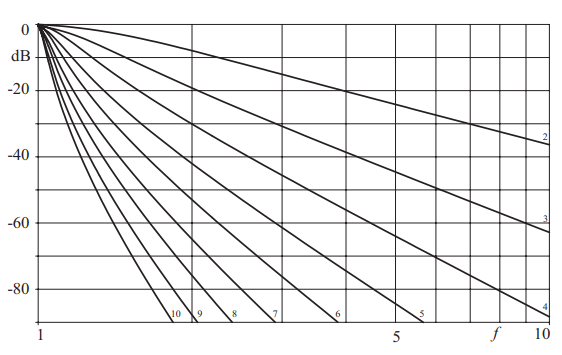

*Appunti di elettronica applicata (prof. Claudio Sansoè) - cap.3 pag.39*

The curves inside the graph tell us the degree of the filter we'll need to build. The number of cells will be equal to the degree divided by two.

For odd degrees, the second-order cells will be preceded by a first-order cell. Usually, if the gain isn't very high, it tends to be all on the first cell, in order to limit the noise coming out of the filter.

From the Texas Instrument (cap.16 pag.58) document we can extract all parameters that we need to compute the components:

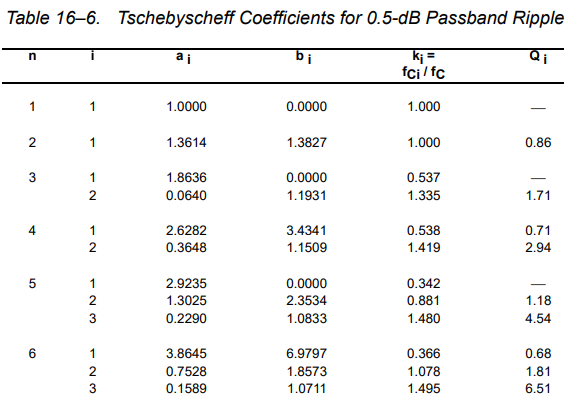

## First Order Filter

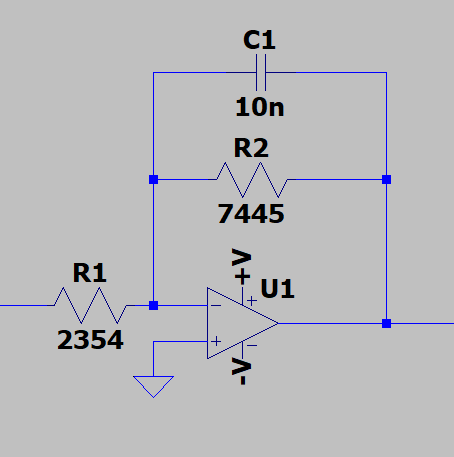

k0 = 0.342;           % GIVEN (from table)
C1 = 10 *1e-9; %F     % TO BE DECIDED
A0 = A;               % this can be changed dividing the amplification between the different cells

f0 = f_off*k0;
H = -10^(A0/20);

R2 = 1/(2*pi*f0*C1);
R1 = -R2/H;

disp("First order filter")
disp("R1 = "+ R1)
disp("R2 = "+ R2)
disp("C1 = "+ C1)

## Second Order Filter Multiple feedback topology)

You can find references at pag.18 from Texas Instrument document. (obviously this section will have to be performed several times to satisfy the cell grade requirement by changing the parameters)

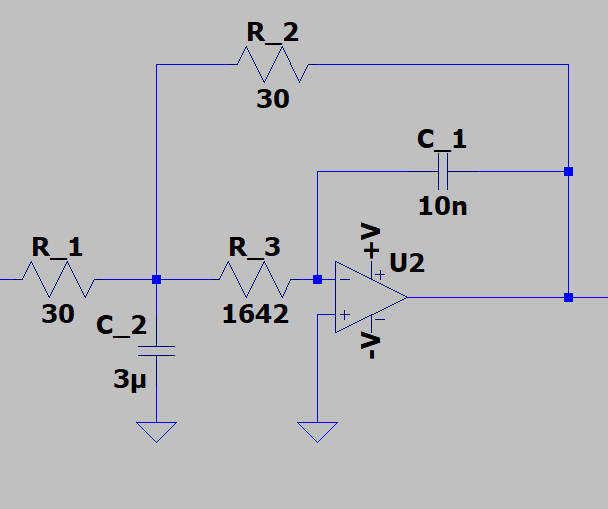

a1 = 1.3025;                   % COMPILE
b1 = 2.3534;                   % COMPILE
k1 = 0.881;                    % COMPILE

A1 = -1;                       % DECIDE
C1 = 10 *1e-9;                 % DECIDE

C2 = C1*(4*b1*(1-A1))/a1^2;  % this is the minimum, capacitor can be bigger
f1 = f_left; %*k1;

R2 = (a1*C2-sqrt(a1^2*C2^2-4*b1*C1*C2*(1-A1)))/(4*pi*f1*C1*C2);
R1 = R2/-A1;
R3 = b1/(4*pi^2*f1^2*C1*C2*R2);

disp("Second order filter (gain)")
disp("R1 = "+ R1)
disp("R2 = "+ R2)
disp("R3 = "+ R3)
disp("C1 = "+ C1)
disp("C2 = "+ C2)

The overall filter will be something like this: